clear, close all, clc

En rapport viser klormængde (mg per liter, y) og bilveje i vandområdet (procent, x).

load('dataset_problem_11_10.mat')
Y_bar = sum(data(:,1))/length(data)

Y_bar = 17.0500

x_bar = sum(data(:,2))/length(data)

x_bar = 0.8061

Opgave a)

Tegn et scatterplot af dataene. Virker en simpel lineær regression korrekt at anvende her?

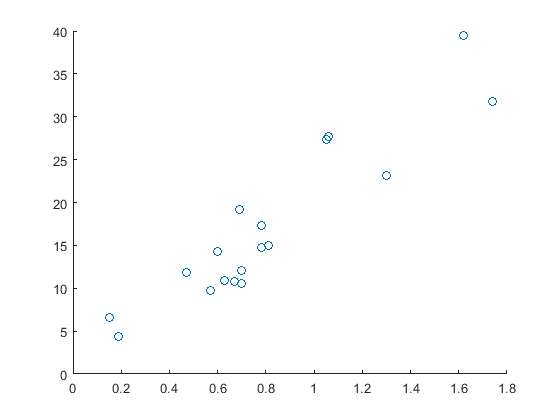

scatter(data(:,2),data(:,1))

Det virker fint at anvende simpel lineær regression.

Opgave b)

Fit en simpel lineær regression til dataene med least-squares metoden. Estimer variansen.

% β_1,hat = sum((xi-x_bar)*(Yi-Y_bar))/(sum(xi-x_bar)^2)
%         = sXY/sXX

sum1 = 0;
sum2 = 0;
for i = 1:length(data)
    sum1 = sum1 + (data(i,2)-x_bar)*(data(i,1)-Y_bar);
    sum2 = sum2 + (data(i,2)-x_bar)^2;
end
beta1_hat = sum1/sum2

beta1_hat = 20.5673

beta0_hat = Y_bar - beta1_hat*x_bar

beta0_hat = 0.4705


% Alternativ: Brug regress(y,x)
[beta,~,r] = regress(data(:,1),[ones(size(data)) data(:,2)])

beta =     0.4705
         0
   20.5673


r =     0.0217
    3.0444
   -2.4938
   -4.2676
   -3.4506
   -2.5279
    1.6629
   -2.7676
    1.4892
   -1.8130



% SSE = sum(Yi-(beta0_hat+beta1_hat*xi)^2)
% σ^2 = SSE/df
% df = n - 2
df = length(data)-2;
sum3 = 0;
for i = 1:length(data)
    sum3 = sum3 + (data(i,1) - (beta0_hat+beta1_hat*data(i,2)))^2;
end
sigma_squared_hat = sum3/df

sigma_squared_hat = 13.8092


% Alternativ: Brug residual fra regress
SSE = sum(r.*r);
sigma_squared_hat = SSE/df

sigma_squared_hat = 13.8092

Opgave c)

Estimer middelværdien af klorkoncentrationen i et område, der har 1% bilvej.

y_1p = beta0_hat + beta1_hat * 1

y_1p = 21.0378

Opgave d)

Find værdien på linjen, der tilhører x = 0,63, og det tilknyttede residual.

y_0punkt63 = beta0_hat + beta1_hat * 0.63

y_0punkt63 = 13.4279

residual0punkt63 = data(6,1) - y_0punkt63

residual0punkt63 = -2.5279